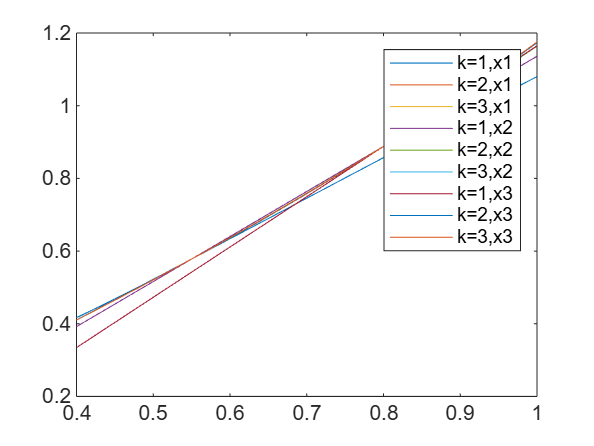

function y_predict = lagrange(x_nodes, y_nodes, x)
    n = length(x_nodes);
    y_predict = 0;
    for i = 1:n
        L = 1;
        for j = 1:n
            if j ~= i
                L = L .* (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        y_predict = y_predict + y_nodes(i) * L;
    end
end

x_data = [0.4, 0.55, 0.8, 0.9, 1.0];
y_data = [0.41075, 0.57815, 0.88811, 1.02652, 1.17520];
x_values = [0.5, 0.7, 0.85];
k_values = [1, 2, 3];
results = zeros(length(x_values), length(k_values));
for x_idx = 1:length(x_values)
    x = x_values(x_idx);
    i = sum(x >= x_data);
    for k_idx = 1:length(k_values)
        k = k_values(k_idx);
        if k == 1
            nodes = [i, i+1];
        elseif k == 2
            if i > 1
                nodes = [i-1, i, i+1];
            else
                nodes = [i, i+1, i+2];
            end
        else
            if i > 1
                nodes = [i-1, i, i+1, i+2];
            else
                nodes = [i, i+1, i+2, i+3];
            end
        end
        nodes = nodes(nodes >= 1 & nodes <= length(x_data));
        x_nodes = x_data(nodes);
        y_nodes = y_data(nodes);
        results(x_idx, k_idx) = lagrange(x_nodes, y_nodes, x);
        x_plot = x_data(1):0.01:x_data(5);
        y_plot = lagrange(x_nodes,y_nodes,x_plot);
        plot(x_plot,y_plot);
        hold on;
        legend('k=1,x1','k=2,x1','k=3,x1','k=1,x2','k=2,x2','k=3,x2','k=1,x3','k=2,x3','k=3,x3')
    end
end

disp(array2table(results))

    results1    results2    results3
    ________    ________    ________

    0.52235      0.5208     0.52111 
    0.76413     0.75948     0.75856 
    0.95731     0.95628     0.95612 

